## 2020年下半年H250的实验数据处理

clc
% 获取control_logger数据表格
ulogOBJ = ulogreader("ExperimentalData\08_11_29.ulg");
msg = readTopicMsgs(ulogOBJ);

## 优化指标

% control_logger = msg.TopicMessages{6};
% % 获取log数据和时间序列
% log_time = control_logger.timestamp;
% fval = control_logger.fval;
% iter = control_logger.iter;
% channel_optimization = control_logger.channel_opti;
% channel = control_logger.channel;
% jmin = control_logger.jmin;
% 
% figure(1)
% % subplot(3,1,1)
% % plot(log_time,jmin,'--','Color','#D95319','LineWidth',1)
% % hold on
% % plot(log_time,fval,"Color",'#0072BD')
% % ylim([-300 0])
% % legend('Optimization Objective Reference','Optimization Objective','box','off','location','southwest');
% tstop = 3800;
% subplot(2,1,1)
% plot(log_time(1:tstop),fval(1:tstop) - jmin(1:tstop),'Color','#D95319','LineWidth',1)
% ylim([-0.1 0.5])
% ylabel('Optimization criterion','Interpreter',"latex")
% 
% subplot(2,1,2)
% plot(log_time(1:tstop),iter(1:tstop),'--',"Color",'#0072BD','LineWidth',1)
% xlabel('Time(s)')
% ylim([0 5])
% ylabel('Iterations','Interpreter',"latex")

## 电机拉力数据

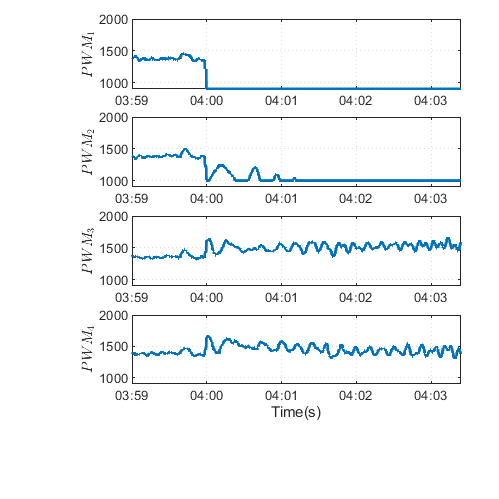

actuator_outputs = msg.TopicMessages{1};
actuator_outputs_time = actuator_outputs.timestamp;
output = actuator_outputs.output;
tstart = 13000;
tstop = 14800;
% 替换冲突数据
for j = 1:4
    for i = 2:tstop
        if output(i,j)==1500
            output(i,j) = output(i-1,j);
        end
    end
end
% 画图
figure(2)
subplot(4,1,1)

plot(actuator_outputs_time(tstart:tstop),output(tstart:tstop,1),"Color",'#0072BD','LineWidth',2);
ylim([900 2000]);
xlim([duration(0,3,59),duration(0,4,03,400)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel('$PWM_{1}$','Interpreter',"latex");

subplot(4,1,2)
plot(actuator_outputs_time(tstart:tstop),output(tstart:tstop,2),"Color",'#0072BD','LineWidth',2);
ylim([900 2000]);
xlim([duration(0,3,59),duration(0,4,03,400)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel('$PWM_{2}$','Interpreter',"latex");

subplot(4,1,3);
plot(actuator_outputs_time(tstart:tstop),output(tstart:tstop,3),"Color",'#0072BD','LineWidth',2);
ylim([900 2000]);
xlim([duration(0,3,59),duration(0,4,03,400)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel('$PWM_{3}$','Interpreter',"latex");


subplot(4,1,4);
plot(actuator_outputs_time(tstart:tstop),output(tstart:tstop,4),"Color",'#0072BD','LineWidth',2);
ylim([900 2000]);
xlim([duration(0,3,59),duration(0,4,03,400)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel('$PWM_{4}$','Interpreter',"latex");
xlabel('Time(s)');

## 获取角速率数据

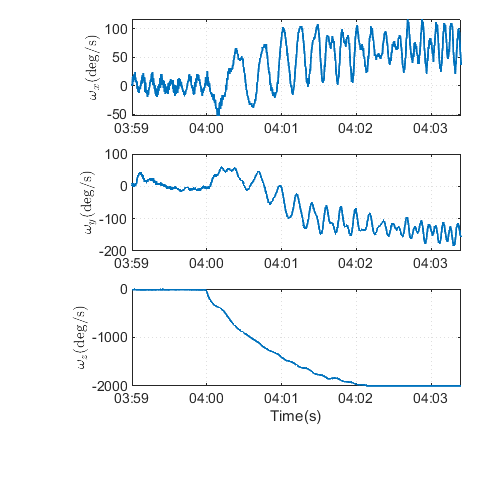

sensor_combine = msg.TopicMessages{12};
gyro = sensor_combine.gyro_rad;
% sensor_time1 = 0:0.005:207.445;
sensor_time = sensor_combine.timestamp;
figure(3)
tstart = 11500;
tstop = 13000;
subplot(3,1,1)
plot(sensor_time(tstart:tstop), gyro(tstart:tstop,1)*180/pi,"Color",'#0072BD','LineWidth',1.5)
% ylim([-4 4])
xlim([duration(0,3,59),duration(0,4,03,400)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel("$\omega_x$(deg/s)",'Interpreter',"latex")


subplot(3,1,2)
plot(sensor_time(tstart:tstop), gyro(tstart:tstop,2)*180/pi,"Color",'#0072BD','LineWidth',1.5)
% ylim([-4 4])
xlim([duration(0,3,59),duration(0,4,03,400)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel("$\omega_y$(deg/s)",'Interpreter',"latex")


subplot(3,1,3)
plot(sensor_time(tstart:tstop), gyro(tstart:tstop,3)*180/pi,"Color",'#0072BD','LineWidth',1.5)
% ylim([-40, 5])
xlim([duration(0,3,59),duration(0,4,03,400)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
ylabel("$\omega_z$(deg/s)",'Interpreter',"latex")
xlabel("Time(s)")

## 滤波姿态

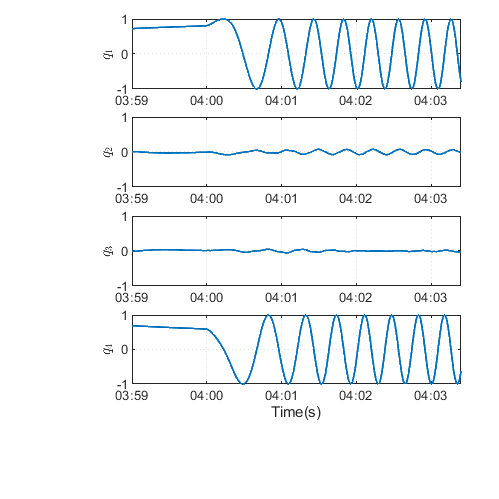

attitude = msg.TopicMessages{17};
attitude_time = attitude.timestamp;
q = attitude.q;

figure(4)
subplot(4,1,1)
plot(attitude_time,q(:,1),"Color",'#0072BD','LineWidth',1.5);
ylabel('$q_1$','Interpreter',"latex")
xlim([duration(0,3,59),duration(0,4,03,400)])
ylim([-1,1])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';

subplot(4,1,2)
plot(attitude_time,q(:,2),"Color",'#0072BD','LineWidth',1.5);
ylabel('$q_2$','Interpreter',"latex")
xlim([duration(0,3,59),duration(0,4,03,400)])
ylim([-1,1])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';

subplot(4,1,3)
plot(attitude_time,q(:,3),"Color",'#0072BD','LineWidth',1.5);
ylabel('$q_3$','Interpreter',"latex")
xlim([duration(0,3,59),duration(0,4,03,400)])
ylim([-1,1])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';

subplot(4,1,4)
plot(attitude_time,q(:,4),"Color",'#0072BD','LineWidth',1.5);
ylabel('$q_4$','Interpreter',"latex")
xlim([duration(0,3,59),duration(0,4,03,400)])
ylim([-1,1])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
xlabel('Time(s)')

## 主轴n3

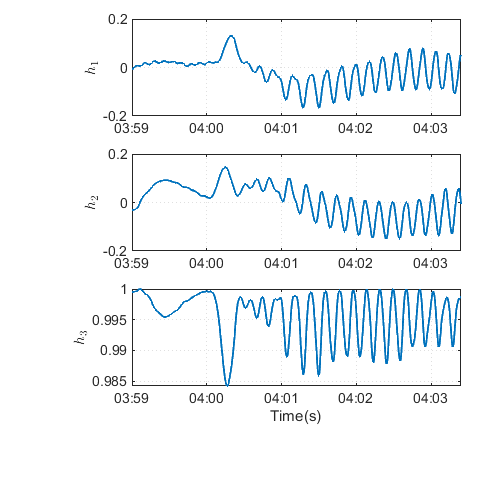

for i=1:14135
    N3(i,:) = quad2dcm(q(i,:));
end

figure(5)
subplot(3,1,1)
plot(attitude_time,N3(:,1),"Color",'#0072BD','LineWidth',1.5)
xlim([duration(0,3,59),duration(0,4,03,400)])
ylabel('$h_1$','Interpreter',"latex")
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';

subplot(3,1,2)
plot(attitude_time,N3(:,2),"Color",'#0072BD','LineWidth',1.5)
xlim([duration(0,3,59),duration(0,4,03,400)])
ylabel('$h_2$','Interpreter',"latex")
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';

subplot(3,1,3)
plot(attitude_time,N3(:,3),"Color",'#0072BD','LineWidth',1.5)
xlim([duration(0,3,59),duration(0,4,03,400)])
ylabel('$h_3$','Interpreter',"latex")
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
xlabel('Time(s)')

## 位置

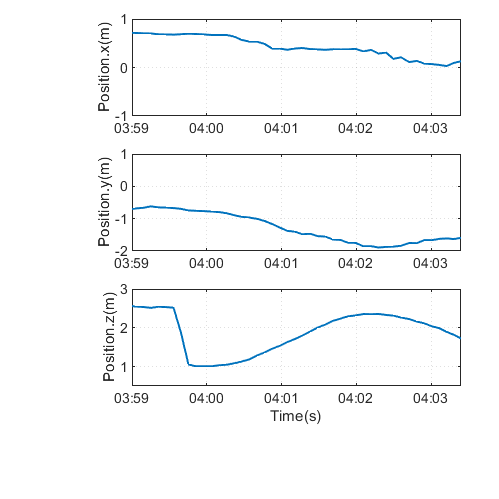

position = msg.TopicMessages{22};
position_time = position.timestamp;
figure(6)
subplot(3,1,1)
plot(position_time,position.x,"Color",'#0072BD','LineWidth',1.5)
ylim([-1,1])
ylabel('Position.x(m)')
xlim([duration(0,3,59),duration(0,4,03,400)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';

subplot(3,1,2)
plot(position_time,position.y,"Color",'#0072BD','LineWidth',1.5)
ylim([-2,1])
ylabel('Position.y(m)')
xlim([duration(0,3,59),duration(0,4,03,400)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';

subplot(3,1,3)
plot(position_time,-position.z,"Color",'#0072BD','LineWidth',1.5)
ylim([0.5,3])
ylabel('Position.z(m)')
xlim([duration(0,3,59),duration(0,4,03,400)])
ax = gca;
ax.XAxis.TickLabelFormat = 'mm:ss';
xlabel('Time(s)')